# Getting Started with Database Explorer for IIASA

## Using the data explorer App

The best way to explore databases is to simply use the app

## Create a Connection

The connection can be created with a default selected scenario or completely empty

c = iiasa.IIASAConnection('ngfs');

At any point in time, a user can view all the available environments in the database:

c.getEnvironments

ans = 14×5 table
                            productName                                     env                                        uiUrl                                         name                          scheme             
    ___________________________________________________________    _____________________    ____________________________________________________________    _______________________    _______________________________

    "CD-LINKS Scenario Explorer hosted by IIASA"                   "cdlinks"                "https://data.ene.iiasa.ac.at/cd-links"                         "IXSE_CDLINKS"             "IXMP Scenario Explorer SPA UI"
    "Chinese Model Intercomparison"                                "cmin"                   "https://data.ene.iiasa.ac.at/cmin-explorer"                    "IXSE_CMIN"

## Exploring the databases

Although the Connection class allows you to perform various REST calls, the best way to explore a database is to use the enviornment class:

### View Models, Scenarios, and Variables

e = iiasa.IIASAEnvironment(c)

e =   IIASAEnvironment with properties:

    Environment: "NGFS Scenario Explorer"
         Models: [6×2 table]
      Scenarios: [8×2 table]
      Variables: [543×4 table]
        Regions: [68×5 table]
        RunList: [34×17 table]
       Metadata: []


This object loads by default all the available Models, Scenarios, Variables, Regions and Runs in the database. For example, you can view all the models by running:

head(e.Variables)

ans = 8×4 table
    ID                      Name                     Unit ID          Unit       
    ___    ______________________________________    _______    _________________

    203    "Agricultural Demand"                       112      "million t DM/yr"
    238    "Agricultural Production"                   112      "million t DM/yr"
     16    "Capacity|Electricity"                       11      "GW"             
     45    "Capacity|Electricity|Biomass"               11      "GW"             
    177    "Capacity|Electricity|Biomass|w/ CCS"        11      "GW"             
    121    "Capacity|Electricity|Biomass|w/o CCS"       11      "GW"             
    151    "Capacity|Electricity|Coal"                  11      "GW"             
    189    "Capacity|Electricity|Coal|w/ CCS"           11      "GW"             


The environment also allows you to change the underlying database:

e.changeEnvironment('iamc15');
disp(e)

  IIASAEnvironment with properties:

    Environment: "IAMC 1.5°C Scenario Explorer hosted by IIASA"
         Models: [25×2 table]
      Scenarios: [177×2 table]
      Variables: [598×4 table]
        Regions: [7×5 table]
        RunList: [416×17 table]
       Metadata: []



head(e.Models)

ans = 8×2 table
    ID                         Name                     
    __    ______________________________________________

    2     "AIM/CGE 2.0"                                 
    3     "AIM/CGE 2.1"                                 
    4     "C-ROADS-5.005"                               
    5     "GCAM 4.2"                                    
    6     "GENeSYS-MOD 1.0"                             
    7     "IEA Energy Technology Perspective Model 2017"
    8     "IEA World Energy Model 2017"                 
    9     "IMAGE 3.0.1"                                 


### Querying Datasets

There are different options to query and select timeseries within the database:

#### Both Model and Scenario are known:

In that case, one can request all the information from the database:

However, this query can be quite length as there are many different variables and regions that will be requested. Alternatively, the data can be fildtered down by "regions" and "variables as:

ts = e.getTimeSeries('model','AIM/CGE 2.0','scenario','ADVANCE_2020_1.5C-2100','regions','World','Variables','Emissions|CO2')

ts =   12×1 IIASATimeseries array with properties:

    Model
    Scenario
    Variable
    Region
    Unit
    RunId
    Version
    Years
    Values


The data returned by the server is always stored in an array of IIASA Timeseries objects. Each of these objects will allow you to automatically plot the data by running:

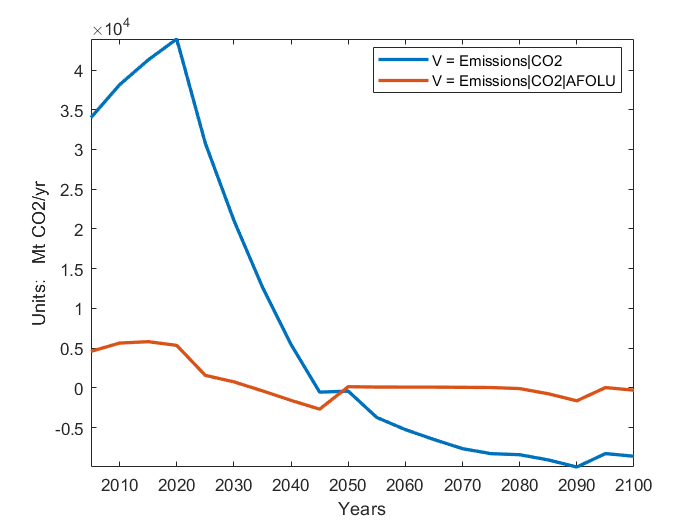

ts(1:2).plot('LineWidth',2);

#### Query by variable / region:

If neither model or scenario are known, it is also possible to query the data using only the filter values, for example:

e.changeEnvironment('ngfs');

ts = e.getTimeSeries('variables',"Emissions|CO", 'regions', "World");
[ts.Variable]'

ans = 300×1 string array
    "Emissions|CO"
    "Emissions|CO2|AFOLU"
    "Emissions|CO2|Energy"
    "Emissions|CO2|Energy|Supply"
    "Emissions|CO2|Energy|Supply|Electricity"
    "Emissions|CO2|Energy and Industrial Processes"
    "Emissions|CO2|Industrial Processes"
    "Emissions|CO2|Energy|Demand|Industry"
    "Emissions|CO2|Energy|Demand|Buildings"
    "Emissions|CO2|Energy|Demand|Transportation"
    "Emissions|CO2"
    "Emissions|CO2|Energy|Demand"
    "Emissions|CO"
    "Emissions|CO2|AFOLU"
    "Emissions|CO2|Energy"
    "Emissions|CO2|Energy|Supply"
    "Emissions|CO2|Energy|Supply|Electricity"
    "Emissions|CO2|Energy and Industrial Processes"
    "Emissions|CO2|Industrial Processes"
    "Emissions|CO2|Energy|Demand|Industry"
    "Emissions|CO2|Energy|Demand|Buildings"
    "Emissions|CO2|Energy|Demand|Transportation"
    "Emissions|CO2"
    "Emissions|CO2|Energy|Demand"
    "Emissions|CO"
    "Emissions|CO2|AFOLU"
    "Emissions|CO2|Energy"
    "Emissions|CO2|Energy|Supply"

If multiple datrasets are returned, the plot command will plot all, or a subsection of them:

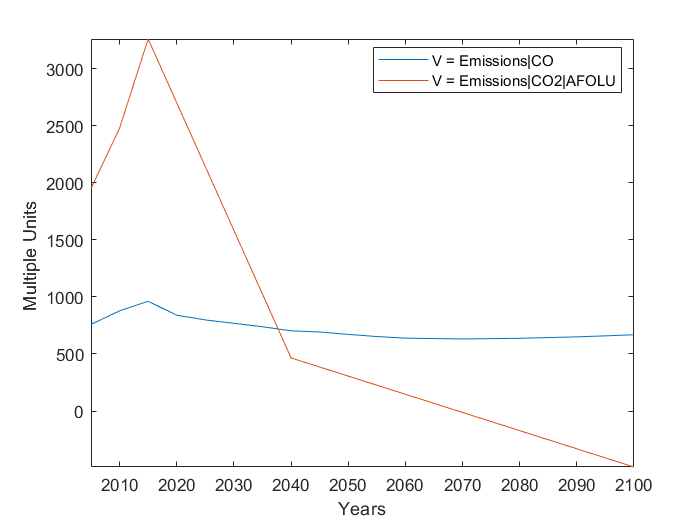

ts(1:2).plot();

For simplicity, the legend will only plot those variables that are different in each curve. For example, the previous plot have equal model, scenario, run, and region. So the legend only reports the different variable.

### Strict versus relaxed queries

By default, the queries will report any partial match to the dataset you enter. For example, the previous query returned all variables containing Emissions|CO. However, if we wanted a strict match to our inputs we could run:

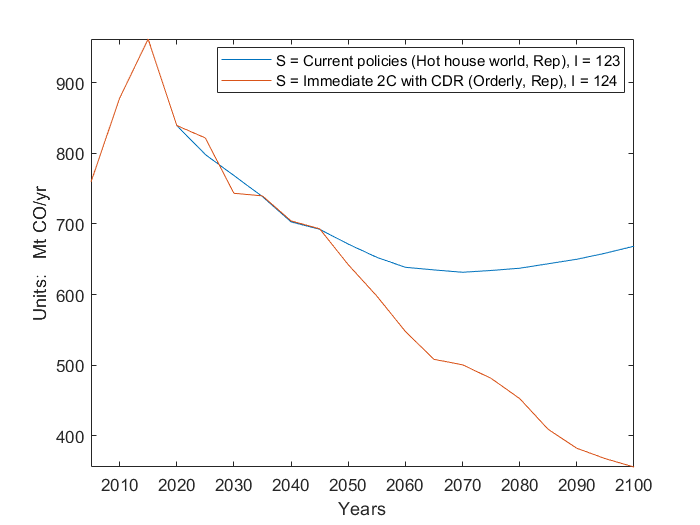

ts = e.getTimeSeries('variables',"Emissions|CO", 'regions', "World", 'strict',true);
ts(1:2).plot();

### Filtering variables

The getTimeSeries only accepts a single "strict" command. However, we can still manually filter our results by running:

e.filterVariables('emissions',false)

ans = 32×1 string array
    "Diagnostics|Emissions|Kyoto Gases|Harmonized (GWP-100 AR5)"
    "Emissions|BC"
    "Emissions|CH4"
    "Emissions|CH4|AFOLU"
    "Emissions|CH4|Energy"
    "Emissions|CH4|Other"
    "Emissions|CO"
    "Emissions|CO2"
    "Emissions|CO2|AFOLU"
    "Emissions|CO2|Energy"
    "Emissions|CO2|Energy and Industrial Processes"
    "Emissions|CO2|Energy|Demand"
    "Emissions|CO2|Energy|Demand|Buildings"
    "Emissions|CO2|Energy|Demand|Industry"
    "Emissions|CO2|Energy|Demand|Transportation"
    "Emissions|CO2|Energy|Supply"
    "Emissions|CO2|Energy|Supply|Electricity"
    "Emissions|CO2|Industrial Processes"
    "Emissions|F-Gases"
    "Emissions|Kyoto Gases"
    "Emissions|N2O"
    "Emissions|N2O|AFOLU"
    "Emissions|N2O|Energy"
    "Emissions|N2O|Other"
    "Emissions|NH3"
    "Emissions|NOx"
    "Emissions|NOx"
    "Emissions|OC"
    "Emissions|PFC"
    "Emissions|SF6"


e.filterVariables('Emissions|CO',true)

ans = "Emissions|CO"

This same process can be done with regions

e.filterRegions('japan',false)

ans = 4×1 string array
    "GCAM 5.2|Japan"
    "REMIND-MAgPIE 1.7-3.0|Japan"
    "Asian countries except Japan"
    "State of Japan"


e.filterRegions('State of Japan',true)

ans = "State of Japan"

and with model/scenarios to find out exact runs:

runs = e.filterRuns('model','GCAM','scenario','immediate','strict',false);
e.RunList(ismember(e.RunList.run_id,runs),1:8)

ans = 2×8 table
          model                         scenario                      scheme                  annotation                 metadata      run_id    model_id    scen_id
    _________________    ______________________________________    ____________    ________________________________    ____________    ______    ________    _______

    "GCAM 5.2"           "Immediate 2C with CDR (Orderly, Rep)"    {0×0 double}    "update of investment variables"    {1×1 struct}     124          1         33   
    "damage_GCAM 5.2"    "Immediate 2C with CDR (Orderly, Rep)"    {0×0 double}    "adding damage variables"           {1×1 struct}     142         61         33   


## Working with the IIASA Timeseries

### Plotting Data

A stack of IIASATimeseries objects can be plot in two main ways: line and bar plots. All plotting functions have two outputs: the array of graphics objects, and the legened. 

#### Line Plots

The data in the object can be plotted as a set of line plots. The plot funciton accepts the exact same options as the standard plot function in MATLAB. For exaple:

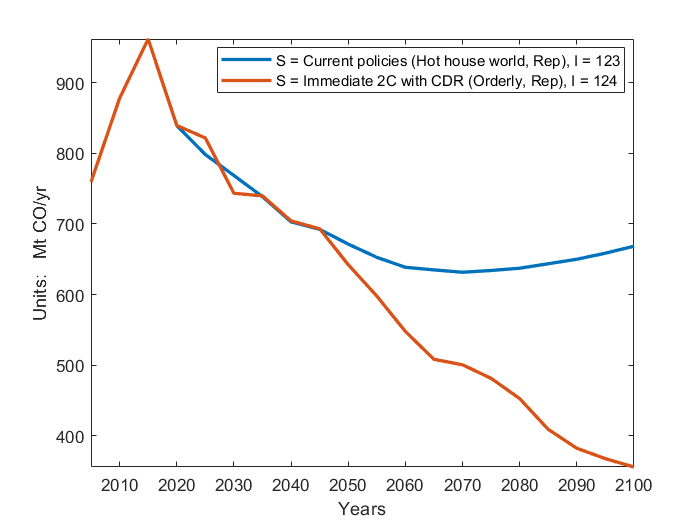

figure;
ts(1:2).plot('LineWidth',2);

#### Bar Plots

Alternatively, the data in the object can also be plotted as a set of bar plots. The bar funciton accepts the exact same options as the standard bar funciton in MATLAB.

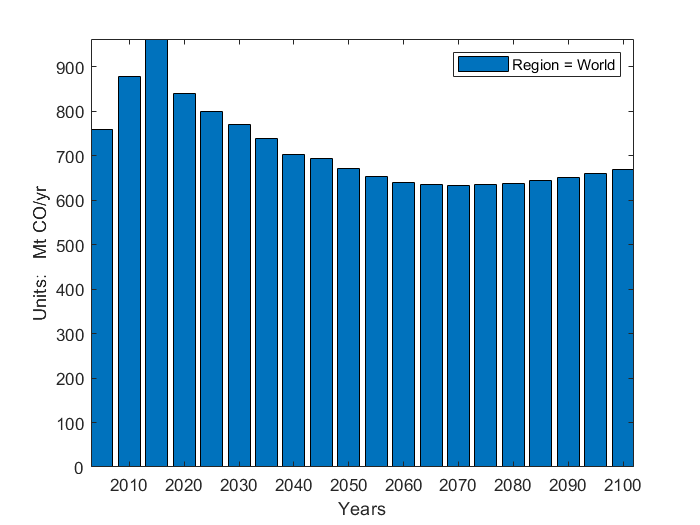

figure;
[~,l] = ts(1).bar();
l.Location = 'northeast';

One useful utility consists in making a stack plot of several data. For example:

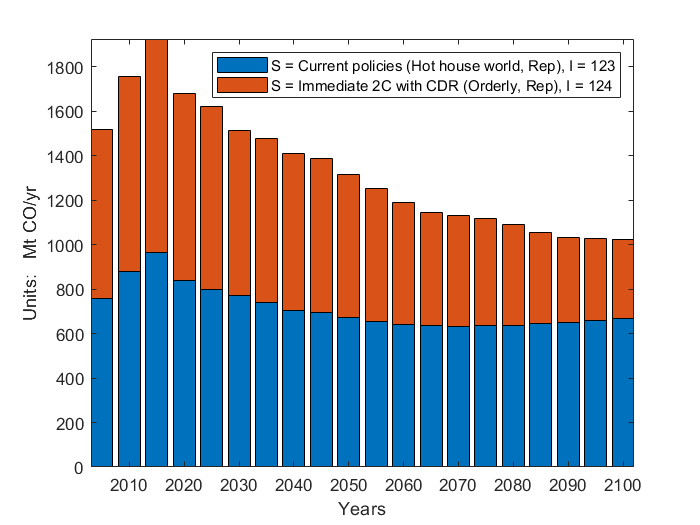

figure;
[h,l] = bar(ts(1:2),'stacked');
l.Location = 'northeast';